close all, clear

% Parámetros para la generación de señales
SIGNALS_POR_MODULACION = 2;
SNR = -30:5:60;
LONGITUD_SIGNAL = 1000;

% Parámetros comunes para las señales
Fs = 1000;           % Frecuencia de muestreo en Hz
t = 0:1/Fs:1;        % Vector de tiempo de 1 segundo
Fc = 100;            % Frecuencia de la portadora en Hz
fm = 20;             % Frecuencia de la señal moduladora en Hz

% Información transmitida
N = 600;                         % Número de bits
m = cos(2*pi*fm*t);  % Señal moduladora
dataBits = randi([0 1], N, 1);   % Vector de bits aleatorios

bitrate = 200; %bits por segundo

duracion_total_s = length(dataBits)/bitrate;
duracionbit = 1/bitrate;
muestras_bit = Fs*duracionbit;
freqdev = 200e3;



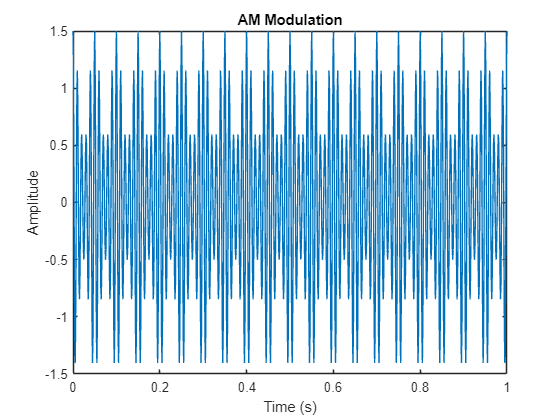



%% Modulación de Amplitud (AM)
Am = 1;              % Amplitud de la portadora
Ac = Am / 2;         % Coeficiente de modulación
sAM = (1 + Ac*m) .* cos(2*pi*Fc*t);
figure
plot(t, sAM); 
title('AM Modulation')
xlabel('Time (s)')
ylabel('Amplitude');

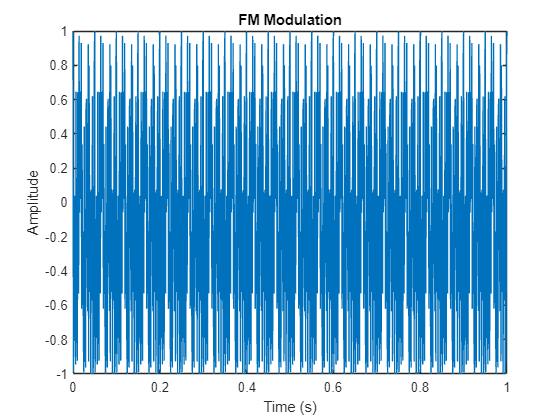




%% Modulación de Frecuencia (FM)
sFM= fmmod( m, Fc , Fs , freqdev );
figure
plot(t, sFM)
title('FM Modulation')
xlabel('Time (s)')
ylabel('Amplitude');

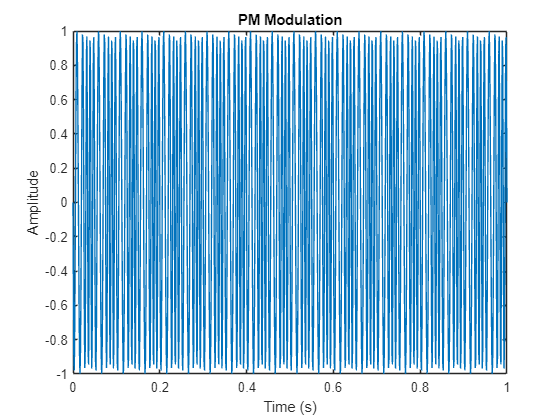


%% Modulación de Fase (PM)
phasedev =pi/2;
sPM = pmmod(m,Fc,Fs,phasedev);
figure
plot(t, sPM)
title('PM Modulation')
xlabel('Time (s)')
ylabel('Amplitude');

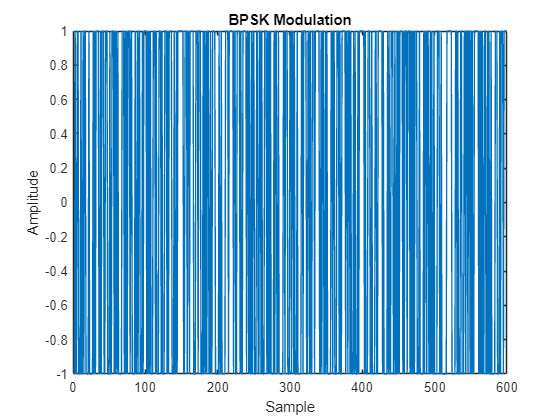


%% BPSK
bpskSig = pskmod(dataBits,2);  % Crear un modulador BPSK
figure
plot(real(bpskSig))
title('BPSK Modulation')
xlabel('Sample')
ylabel('Amplitude');

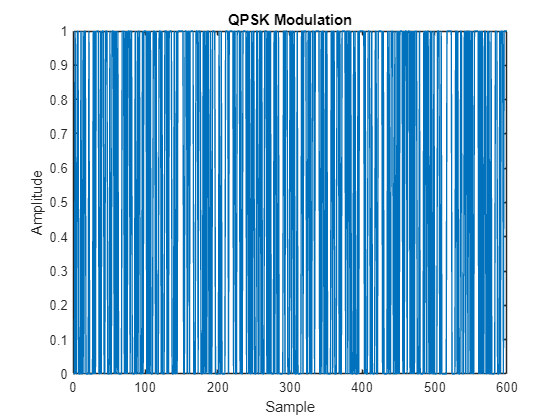


%% QPSK
qpskSig = pskmod(dataBits,4);  % Crear un modulador BPSK
figure; plot(real(qpskSig))
title('QPSK Modulation')
xlabel('Sample')
ylabel('Amplitude');

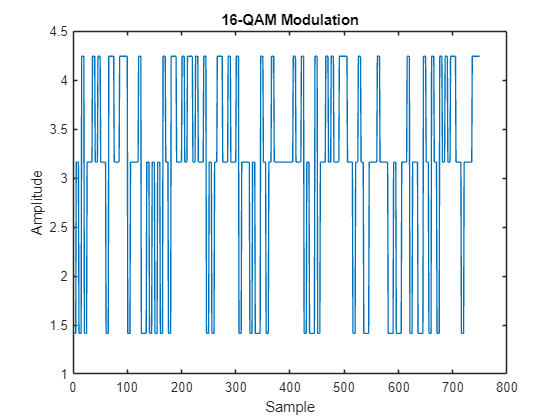


%% 16-QAM
M = 16;                                        % Orden de la modulación
qam16Sig = qammod(dataBits,M,InputType="bit");    % Crear un modulador 16-QAM
% Se repiten las muestras para ajustarlo a Fs
qam16Sig = repelem(qam16Sig,muestras_bit);
figure
plot(abs(qam16Sig))
title('16-QAM Modulation')
xlabel('Sample')
ylabel('Amplitude');

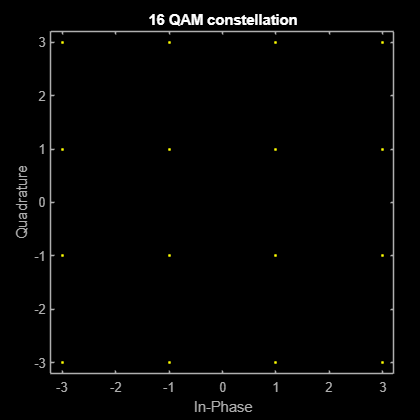


scatterplot(qam16Sig)
title("16 QAM constellation")

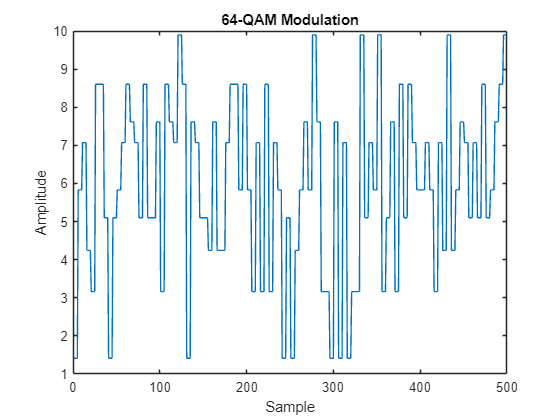


%% 64-QAM
M = 64;                                        % Orden de la modulación
qam64Sig = qammod(dataBits,M,InputType="bit");     % Crear un modulador 64-QAM
qam64Sig = repelem(qam64Sig,muestras_bit);

figure; 
plot(abs(qam64Sig)); 
title('64-QAM Modulation'); 
xlabel('Sample');
ylabel('Amplitude');

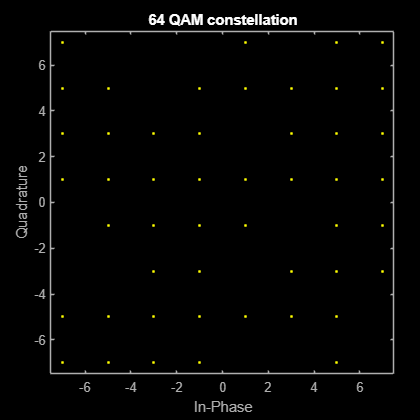


scatterplot(qam64Sig)
title("64 QAM constellation")

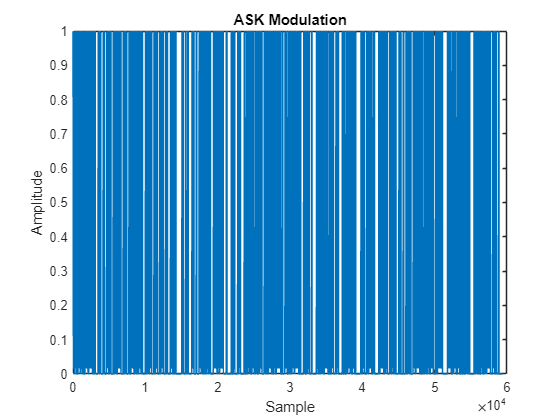

%% ASK modulation
A1=1;      % Amplitude of carrier signal for information 1
A2=0;       % Amplitude of carrier signal for information 0
bp = 1/bitrate;
f=bitrate*10;    % carrier frequency
t2=bp/99:bp/99:bp;
ss=length(t2);
askSig=[];
for i=1:1:length(dataBits)
    if dataBits(i)==1
        y=A1*cos(2*pi*f*t2);
    else
        y=A2*cos(2*pi*f*t2);
    end
    askSig=[askSig y];
end

figure; 
plot(abs(askSig)); 
title('ASK Modulation'); 
xlabel('Sample');
ylabel('Amplitude');

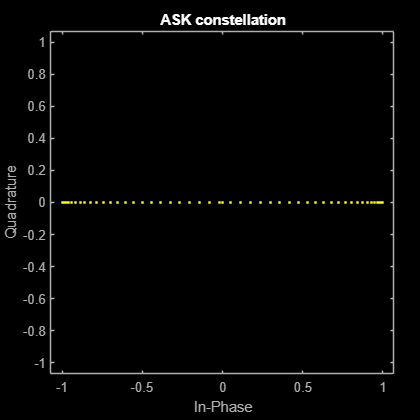


scatterplot(askSig)
title("ASK constellation")

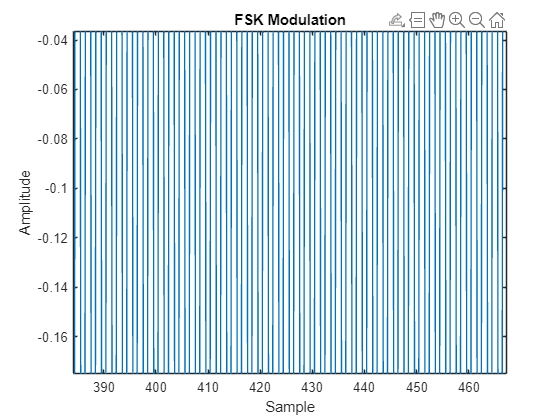

%% FSK modulation
M= 2;
freq_sep = 1e3;
nsamp = 2;
fskSig = fskmod(dataBits,M,freq_sep,nsamp,Fs);
figure; 
plot(real(fskSig)); 
title('FSK Modulation'); 
xlabel('Sample');
ylabel('Amplitude');

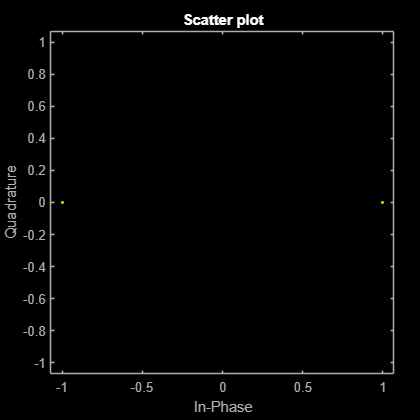

scatterplot(fskSig)